## Read and filter the data 

Including location derivatives dx/dt and dy/dt in columns 25 and 26 respectively.

clear all, close all;
temp = csvread('trajectories-0830-0845-data_vel.csv');
train_clustering = temp(temp(:, 6) >= 350 & temp(:, 6)< 450 & temp(:, 5)> -5 & temp(:, 5) < 85, :);
scatter(train_clustering(:,5),train_clustering(:,6), 'g.', 'MarkerEdgeAlpha', 0.2 , 'MarkerFaceAlpha', 0.2);
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');
clear temp;

## Generating clustering input data 

unique_IDs = unique(train_clustering(:,1));
numOfVeh = size(unique_IDs, 1);
start_end = zeros(numOfVeh,9);
for i =1:numOfVeh
    a = train_clustering(train_clustering(:,1) == unique_IDs(i),:);
    start_end(i,1) = unique_IDs(i);
    start_end(i,2:3) = a(1,5:6);
    start_end(i,4:5) = a(end,5:6);
    start_end(i,6:7) = a(1,25:26);
    start_end(i,8:9) = a(end,25:26);
end

## Clustering

number_of_clusters = 10;

clusters = kmeans(start_end(:,2:9),number_of_clusters);
% clusters = clusterdata(start_end(:,2:5), 'distance', 'Euclidean', 'linkage' , 'average', 'cutoff', 0.2); 
clusters = [clusters , start_end(:,1)];
keySet = clusters(:,2);
valueSet = clusters(:,1);
id_cluster_map = containers.Map(keySet,valueSet);

## Concating the cluster number as the last column of the data

for i =1:size(train_clustering,1)
    train_clustering(i,27) = id_cluster_map(train_clustering(i,1));
end

## Plotting different clusters 

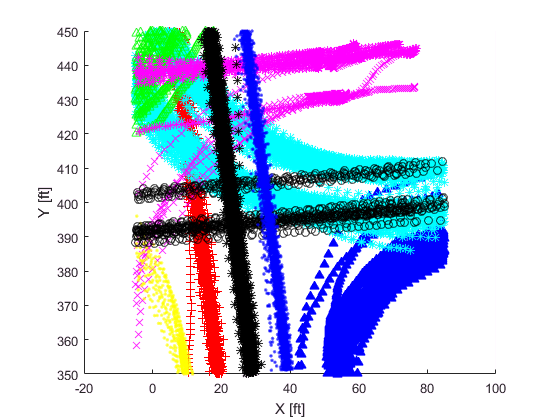

MarkerEdgeAlpha = 0.8;
scatter(train_clustering(train_clustering(:,27) == 1,5),train_clustering(train_clustering(:,27) == 1,6), 'b^', 'MarkerFaceColor', 'blue');
hold on;
scatter(train_clustering(train_clustering(:,27) == 2,5),train_clustering(train_clustering(:,27) == 2,6), 'r+', 'MarkerFaceColor', 'red');
hold on;
scatter(train_clustering(train_clustering(:,27) == 3,5),train_clustering(train_clustering(:,27) == 3,6), 'c*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 4,5),train_clustering(train_clustering(:,27) == 4,6), 'g^', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 5,5),train_clustering(train_clustering(:,27) == 5,6), 'mx', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 6,5),train_clustering(train_clustering(:,27) == 6,6), 'y.' , 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 7,5),train_clustering(train_clustering(:,27) == 7,6), 'k', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 8,5),train_clustering(train_clustering(:,27) == 8,6), 'm*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 9,5),train_clustering(train_clustering(:,27) == 9,6), 'k*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(train_clustering(train_clustering(:,27) == 10,5),train_clustering(train_clustering(:,27) == 10,6), 'b.', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');
hold off;

## Training Gaussian Process models for different clusters

temp = train_clustering(train_clustering(:,27) == 4, :);
unique_IDs = unique(temp(:,1));
numOfVeh = size(unique_IDs, 1);
train = [];
for i =1:10
    train= [train;temp(temp(:,1) == unique_IDs(i),:)];
end
% Preparing the GP parameters and hyperparameters
covfunc = @covSEiso; 
likfunc = @likGauss; sn = 0.1; hyp.lik = log(sn);

% Running GP for vx
hyp_vx_4.cov = [0 ; 0];    
hyp_vx_4.lik = log(0.1);
hyp_vx_4 = minimize(hyp_vx_4, @gp, -100, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25));

Function evaluation      0;  Value 1.503163e+02
Function evaluation      8;  Value 6.269377e+01
Function evaluation     10;  Value 2.351805e+01
Function evaluation     13;  Value 2.133378e+01
Function evaluation     15;  Value 1.742653e+01
Function evaluation     18;  Value 1.741980e+01
Function evaluation     21;  Value 1.738774e+01
Function evaluation     23;  Value 1.737681e+01
Function evaluation     25;  Value 1.737240e+01
Function evaluation     28;  Value 1.737239e+01
Function evaluation     30;  Value 1.737238e+01
Function evaluation     32;  Value 1.737238e+01
Function evaluation     34;  Value 1.737238e+01
Function evaluation     36;  Value 1.737238e+01
Function evaluation     38;  Value 1.737238e+01
Function evaluation     40;  Value 1.737238e+01
Function evaluation     43;  Value 1.737238e+01
Function evaluation     45;  Value 1.737238e+01


exp(hyp_vx_4.lik)

ans = 0.2204

nlml_vx = gp(hyp_vx_4, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25));

% Running GP for vy
hyp_vy_4.cov = [0 ; 0];    
hyp_vy_4.lik = log(0.1);
hyp_vy_4 = minimize(hyp_vy_4, @gp, -100, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26));

Function evaluation      0;  Value 2.888216e+02
Function evaluation      7;  Value 2.049677e+02
Function evaluation     10;  Value 1.302040e+02
Function evaluation     12;  Value 5.343937e+01
Function evaluation     14;  Value 5.261212e+01
Function evaluation     16;  Value 5.194577e+01
Function evaluation     19;  Value 4.757938e+01
Function evaluation     22;  Value 4.579903e+01
Function evaluation     24;  Value 4.520676e+01
Function evaluation     26;  Value 4.506216e+01
Function evaluation     28;  Value 4.501475e+01
Function evaluation     30;  Value 4.500185e+01
Function evaluation     32;  Value 4.496141e+01
Function evaluation     34;  Value 4.495057e+01
Function evaluation     37;  Value 4.491027e+01
Function evaluation     41;  Value 4.442360e+01
Function evaluation     43;  Value 4.429557e+01
Function evaluation     45;  Value 4.426367e+01
Function evaluation     47;  Value 4.425317e+01
Function evaluation     49;  Value 4.424820e+01
Function evaluation     51;  Value 4.424

exp(hyp_vy_4.lik)

ans = 0.2969

nlml_vy = gp(hyp_vy_4, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26));
%end

# Testing

## Reading test data

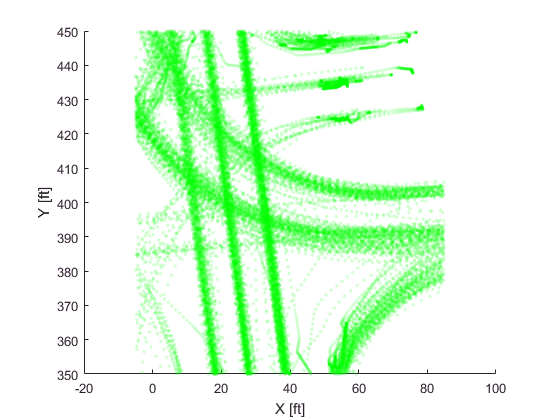

clear test_clustering;
temp = csvread('trajectories-0845-0900-data.csv');
test_clustering = temp(temp(:, 6) >= 350 & temp(:, 6)< 450 & temp(:, 5)> -5 & temp(:, 5) < 85, :);
scatter(test_clustering(:,5),test_clustering(:,6), 'g.', 'MarkerEdgeAlpha', 0.2 , 'MarkerFaceAlpha', 0.2);
test_clustering(:,28) = 0;
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');

clear temp;

## Computing velocities

unique_IDs = unique(test_clustering(:,1));
numOfVeh = size(unique_IDs, 1);
data_Size = size(test_clustering,1);
for i = 1:1:numOfVeh
    current_ID = unique_IDs(i);
    x_last = NaN;
    y_last = NaN;
    for j = 1:1:data_Size
        if (test_clustering(j,1) == current_ID)
            if (~isnan(x_last) && ~isnan(y_last))
                vx =  test_clustering(j,5) - x_last;
                test_clustering(j,25) = vx;
                x_last = test_clustering(j,5);
                
                vy = test_clustering(j,6) - y_last;
                test_clustering(j,26) = vy;
                y_last = test_clustering(j,6);
            else
                x_last = test_clustering(j,5);
                y_last = test_clustering(j,6);
            end
        end
    end
end

csvwrite('trajectories-0845-0900-data_vel.csv',data);

## Generating clustering input data 

unique_IDs = unique(test_clustering(:,1));
numOfVeh = size(unique_IDs, 1);
start_end = zeros(numOfVeh,9);
for i =1:numOfVeh
    a = test_clustering(test_clustering(:,1) == unique_IDs(i),:);
    start_end(i,1) = unique_IDs(i);
    start_end(i,2:3) = a(1,5:6);
    start_end(i,4:5) = a(end,5:6);
    start_end(i,6:7) = a(1,25:26);
    start_end(i,8:9) = a(end,25:26);
end

## Clustering

number_of_clusters = 10;
clusters = kmeans(start_end(:,2:9),number_of_clusters);
% clusters = clusterdata(start_end(:,2:5), 'distance', 'Euclidean', 'linkage' , 'average', 'cutoff', 0.2); 
clusters = [clusters , start_end(:,1)];
keySet = clusters(:,2);
valueSet = clusters(:,1);
id_cluster_map = containers.Map(keySet,valueSet);

## Concating the cluster number as the last column of the data

for i =1:size(test_clustering,1)
    test_clustering(i,27) = id_cluster_map(test_clustering(i,1));
end

## Plotting different clusters 

MarkerEdgeAlpha = 0.8;
scatter(test_clustering(test_clustering(:,27) == 1,5),test_clustering(test_clustering(:,27) == 1,6), 'b^', 'MarkerFaceColor', 'blue');
hold on;
scatter(test_clustering(test_clustering(:,27) == 2,5),test_clustering(test_clustering(:,27) == 2,6), 'r+', 'MarkerFaceColor', 'red');
hold on;
scatter(test_clustering(test_clustering(:,27) == 3,5),test_clustering(test_clustering(:,27) == 3,6), 'c*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 4,5),test_clustering(test_clustering(:,27) == 4,6), 'g^', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 5,5),test_clustering(test_clustering(:,27) == 5,6), 'mx', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 6,5),test_clustering(test_clustering(:,27) == 6,6), 'y.' , 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 7,5),test_clustering(test_clustering(:,27) == 7,6), 'k', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 8,5),test_clustering(test_clustering(:,27) == 8,6), 'm*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 9,5),test_clustering(test_clustering(:,27) == 9,6), 'k*', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
scatter(test_clustering(test_clustering(:,27) == 10,5),test_clustering(test_clustering(:,27) == 10,6), 'b.', 'MarkerEdgeAlpha', MarkerEdgeAlpha , 'MarkerFaceAlpha', MarkerEdgeAlpha);
hold on;
axis manual equal;
xlabel('X [ft]');
ylabel('Y [ft]');
hold off;

% Prediction for a single vehicle
test = test_clustering(test_clustering(:, 1) == 122, :);
scatter(test(:,5),test(:,6), 'b.');
hold on;

steps = size(test,1);
[m_vx s_vx]= gp(hyp_vx, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:steps,5:6));
[m_vy s_vy] = gp(hyp_vy, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:steps,5:6));

% Projection
p = [test(10,5),test(10,6)];
v = [test(10,25),test(10,26)];
a = [test(10,25) - test(1,25) , test(10,26) - test(1,26)];
p1 = p;
v1 = v;

for j = 10:steps
    p = Project(p,[m_vx(j),m_vy(j)]);
    p1 =  Project(p1,v1);
    scatter(p(1),p(2),'r.');
    hold on;
    scatter(p1(1),p1(2),'m.');
    hold on;
end

Prediction 

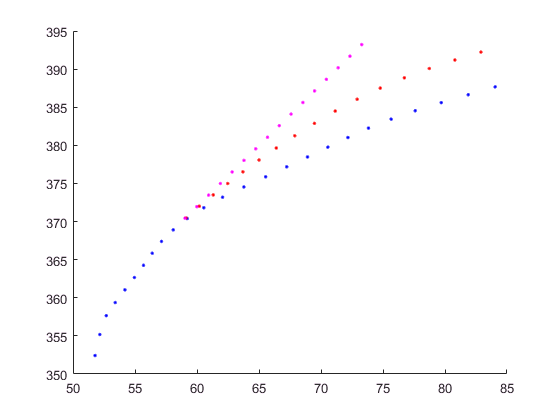

%for i = 1:number_of_clusters
temp = train_clustering(train_clustering(:,27) == 1, :);
unique_IDs = unique(temp(:,1));
numOfVeh = size(unique_IDs, 1);
train = [];
for i =1:10
    train= [train;temp(temp(:,1) == unique_IDs(i),:)];
end


temp = train_clustering(train_clustering(:,27) == 1, :);
unique_IDs = unique(temp(:,1));
numOfVeh = size(unique_IDs, 1);
test = [];
for i =11:20
    test= temp(temp(:,1) == unique_IDs(i),:);
    scatter(test(:,5),test(:,6), 'b.');
    hold on;
    
    steps = size(test,1);
    [m_vx s_vx]= gp(hyp_vx_1, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,25),test(1:steps,5:6));
    [m_vy s_vy] = gp(hyp_vy_1, @infExact, [], covfunc, likfunc, train(:,5:6), train(:,26),test(1:steps,5:6));
    
    % Projection
    p = [test(10,5),test(10,6)];
    v = [test(10,25),test(10,26)];
    a = [test(10,25) - test(1,25) , test(10,26) - test(1,26)];
    p1 = p;
    v1 = v;
    
    for j = 10:steps
        p = Project(p,[m_vx(j),m_vy(j)]);
        p1 =  Project(p1,v1);
        scatter(p(1),p(2),'r.');
        hold on;
        scatter(p1(1),p1(2),'m.');
        hold on;
    end
    hold off;
end